## LBG quantizer on static images

Import the image

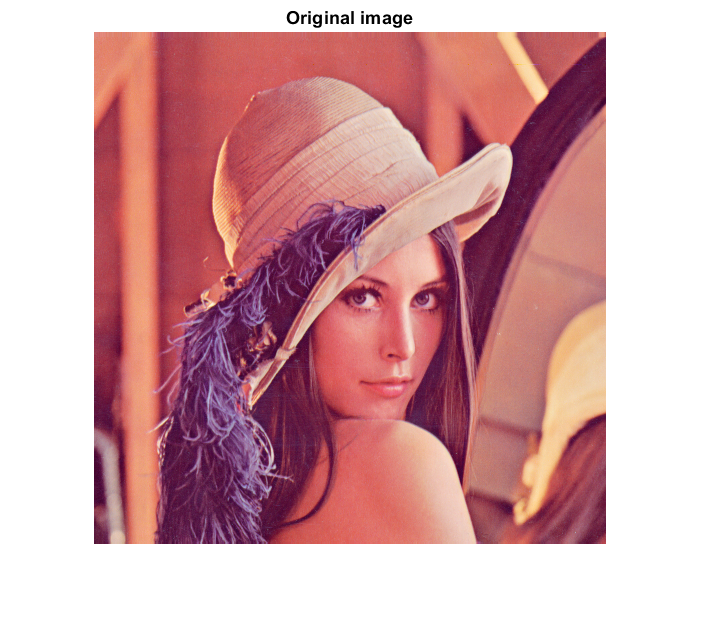

path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\data\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\Data_Set\Images\';
A = imread(strcat(path,'lena.tiff'));
% A = imread(strcat(path, 'lena_full.jfif'));
imshow(A)
title("Original image")

Creating the Codebook with LBG algorithm and splitting technique

global X;
global M;

X = double(reshape(A, [],3))./255;

M = ones(size(X, 1),1);
c0 = sum(X, 1)/length(X);
C = c0;
%test run
for i = 1:8
    C = LBGCentroidSplit(C);
end

% Making a codebook
Codebook = uint8(C*255);

Encoding the image

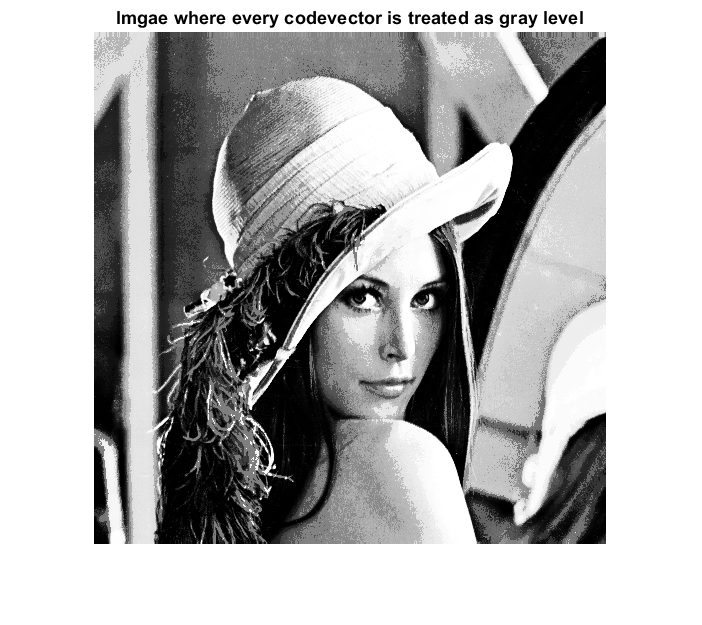

% encoding
A_r = double(reshape(A, [],3));
A_dist = pdist2(A_r, double(Codebook), "euclidean");
[~, A_enc] = min(A_dist, [], 2);
A_enc = uint8(A_enc - 1);

%reshape to original pixel size
A_enc = reshape(A_enc, size(A,1), size(A,2), 1);

imshow(A_enc)
title('Imgae where every codevector is treated as gray level')

Decoding the image

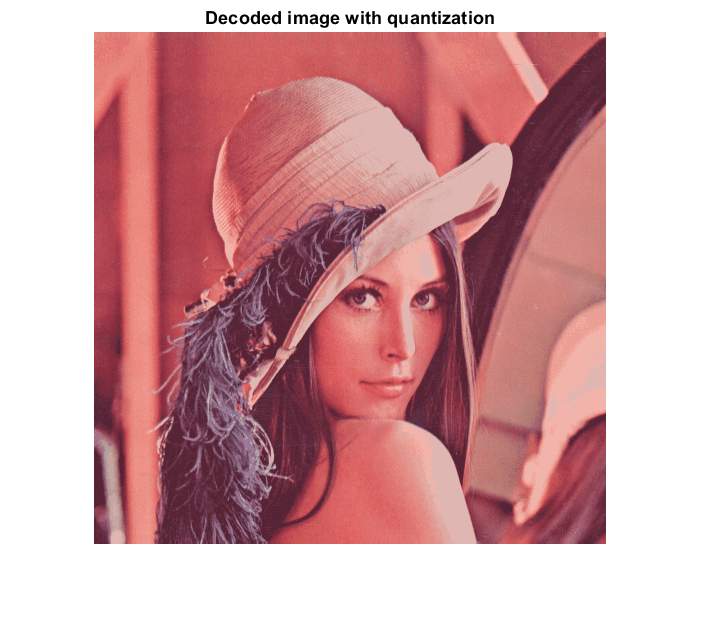

A_enc = reshape(A_enc, [], 1);

% get codevectors, but need to add 1 to the index since Matlab vectors
% start from 1
A_dec = Codebook(A_enc+1,:);
A_dec = uint8(reshape(A_dec, size(A)));

imshow(A_dec)
title("Decoded image with quantization")

Evaluate distortion

[d, dImg] = imageDistortion(A, A_dec);
disp(['Distortion is ', num2str(d)])

Distortion is 0.003227


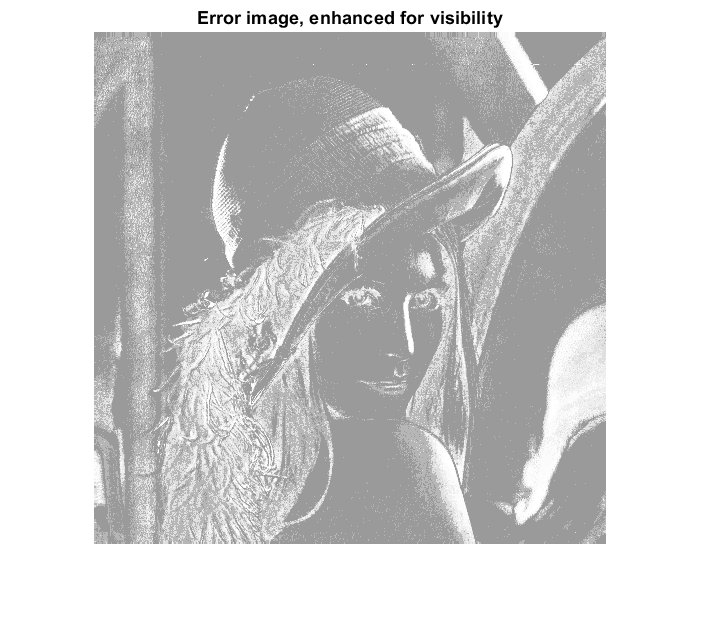

% enhance contrast for easier visualization
J = histeq(dImg);
imshow(J)
title('Error image, enhanced for visibility')